# Get Started with Problem-Based Optimize Live Editor Task

## Include Parameters or Data

Typically, you have data or values to pass to the solver. Place those values in the input section (where you see `x0x` and `x0y`) and run the section by choosing **Section > Run Section** or pressing `Control+Enter`.

clc; clear; close all;

SLL_target_dB = -20; % Change this to run the different cases.
p_initial = [1 1 1 1];

**Place these values and any other problem data into the workspace** by running this section before proceeding.

## Optimize Live Editor Task

Usually, you place the Optimize Live Editor task into the script by selecting **Task > Optimize** in the **Live Editor** tab, or by selecting **Task > Optimize** in the **Insert** tab. Then you are presented with the following choice (this is only a picture, not the real task):

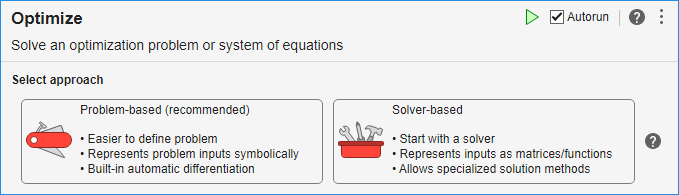

To get the problem-based task, click **Problem-based (recommended)**.

The following problem-based task has the variables, objective, and constraint filled in. Modify it for your problem, or run it as is to see how the task works. To modify the problem, click the **Define problem** button at the bottom of the task. To run the task, click the **Solve problem** button at the bottom of the task.

% Create optimization variables
p = optimvar("p",4,1,"LowerBound",1,"UpperBound",10);

% Set initial starting point for the solver
initialPoint.p = p_initial;

% Create problem
problem = optimproblem;

% Define problem objective
problem.Objective = fcn2optimexpr(@SLL_error,p,SLL_target_dB);

% Set nondefault solver options
options = optimoptions("ga","Display","iter","PlotFcn",["gaplotbestf",...
    "gaplotbestindiv"]);

% Display problem information
show(problem);


  OptimizationProblem : 

	Solve for:
       p

	minimize :
       SLL_error(p, (-20))


	variable bounds:
       1 <= p(1) <= 10
       1 <= p(2) <= 10
       1 <= p(3) <= 10
       1 <= p(4) <= 10




Solving problem using ga.

Single objective optimization:
4 Variables

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              100       0.0004647         0.02581        0
    2              147       3.331e-05          0.0213        0
    3              194       3.331e-05        0.009286        1
    4              241       3.737e-09        0.006434        0
    5              288       3.737e-09        0.003673        1
    6              335       3.737e-09        0.001949        2
    7              382       3.737e-09       0.0008269        3
    8              429       3.737e-09       0.0006112        4
    9              476       3.737e-09       0.0004346        5
   10              523       3.737e-09       0.000

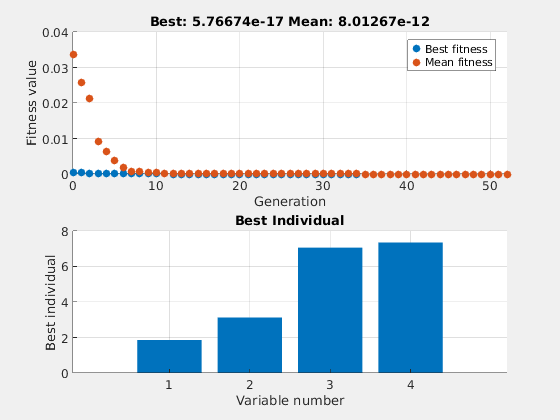


% Solve problem
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint,...
    "Solver","ga","Options",options);


% Display results
solution

solution = struct with fields:
    p: [4×1 double]


reasonSolverStopped

reasonSolverStopped =     SolverConvergedSuccessfully


objectiveValue

objectiveValue = 5.7667e-17


% Clear variables
clearvars p initialPoint options reasonSolverStopped objectiveValue